% Create a 3D grid graph
n = 5; % Dimension of the grid (n x n x n)
grid3D = zeros(n, n, n);
[x, y, z] = meshgrid(1:n);
node_indices = reshape(1:(n*n*n), n, n, n);
grid3D = node_indices;

% Define the source and destination nodes
src = grid3D(1,1,1); % First node
dest = grid3D(n,n,n); % Last node

% Create a 2D adjacency matrix from the 3D grid
adjMatrix = inf(n*n*n);
for x = 1:n
    for y = 1:n
        for z = 1:n
            % For each node, add edges to its neighbors
            curNode = grid3D(x, y, z);
            if x < n
                adjMatrix(curNode, grid3D(x+1, y, z)) = randi([1, 10]);
            end
            if y < n
                adjMatrix(curNode, grid3D(x, y+1, z)) = randi([1, 10]);
            end
            if z < n
                adjMatrix(curNode, grid3D(x, y, z+1)) = randi([1, 10]);
            end
            if x > 1
                adjMatrix(curNode, grid3D(x-1, y, z)) = randi([1, 10]);
            end
            if y > 1
                adjMatrix(curNode, grid3D(x, y-1, z)) = randi([1, 10]);
            end
            if z > 1
                adjMatrix(curNode, grid3D(x, y, z-1)) = randi([1, 10]);
            end
        end
    end
end

% Define some obstacles
obstacles = randi([1, n*n*n], 1, 10); % Randomly generate 10 obstacles

% Set these nodes as obstacles in the adjacency matrix
adjMatrix(obstacles, :) = inf;
adjMatrix(:, obstacles) = inf;

% Apply the Dijkstra algorithm
[dist, path] = Dijkstra(adjMatrix, src, dest);

% Print the result
fprintf('Shortest path from node %d to node %d: %s\n', src, dest, sprintf('%d ', path));

Shortest path from node 1 to node 125: 1 2 7 8 13 38 43 68 93 118 119 120 125 


fprintf('Distance: %d\n', dist(dest));

Distance: 38


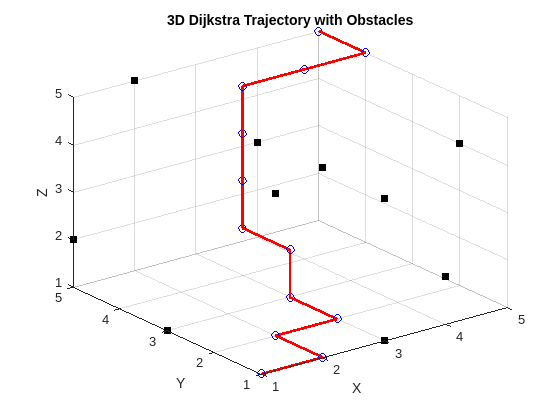


% Convert the path node indices back to (x, y, z) coordinates
path_coords = zeros(length(path), 3);
for i = 1:length(path)
    [x, y, z] = ind2sub(size(grid3D), path(i));
    path_coords(i, :) = [x, y, z];
end

% Convert the obstacles node indices back to (x, y, z) coordinates
obstacles_coords = zeros(length(obstacles), 3);
for i = 1:length(obstacles)
    [x, y, z] = ind2sub(size(grid3D), obstacles(i));
    obstacles_coords(i, :) = [x, y, z];
end

% Plot the 3D trajectory and the obstacles
figure;
plot3(path_coords(:, 1), path_coords(:, 2), path_coords(:, 3), 'r-', 'LineWidth', 2);
hold on;
scatter3(path_coords(:, 1), path_coords(:, 2), path_coords(:, 3), 'bo');
scatter3(obstacles_coords(:, 1), obstacles_coords(:, 2), obstacles_coords(:, 3), 'ks', 'filled');
title('3D Dijkstra Trajectory with Obstacles');
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on;

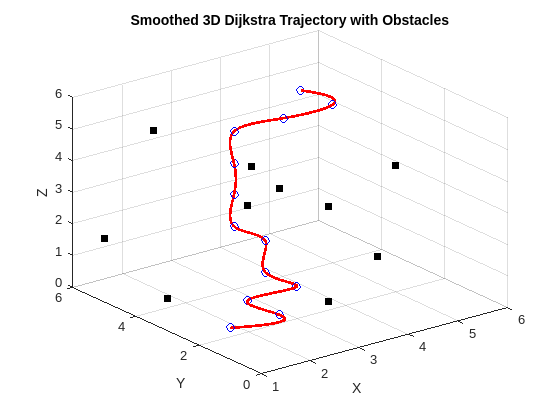

% Perform cubic spline interpolation to smooth the path
num_points = 100; % Number of points to generate for the smooth path
t = 1:length(path_coords);
ts = linspace(1, length(path_coords), num_points);

% Calculate the smoothed coordinates
smooth_x = spline(t, path_coords(:, 1), ts);
smooth_y = spline(t, path_coords(:, 2), ts);
smooth_z = spline(t, path_coords(:, 3), ts);

% Plot the 3D smoothed trajectory and the obstacles
figure;
plot3(smooth_x, smooth_y, smooth_z, 'r-', 'LineWidth', 2);
hold on;
scatter3(path_coords(:, 1), path_coords(:, 2), path_coords(:, 3), 'bo');
scatter3(obstacles_coords(:, 1), obstacles_coords(:, 2), obstacles_coords(:, 3), 'ks', 'filled');
title('Smoothed 3D Dijkstra Trajectory with Obstacles');
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on;

function [dist, path] = Dijkstra(adjMatrix, src, dest)
    % Initialize the distance vector
    dist = inf(size(adjMatrix, 1), 1);
    dist(src) = 0;
    
    % Initialize the previous nodes vector
    prev = -ones(size(adjMatrix, 1), 1);
    
    % The set of unvisited nodes
    Q = 1:size(adjMatrix, 1);
    
    while ~isempty(Q)
        [~, idx_in_Q] = min(dist(Q));
        u = Q(idx_in_Q);
        Q(idx_in_Q) = [];
        
        % The neighbors of u
        neighbors = find(adjMatrix(u, :) > 0);
        for v = neighbors
            alt = dist(u) + adjMatrix(u, v);
            if alt < dist(v)
                dist(v) = alt;
                prev(v) = u;
            end
        end
    end
    
    % Determine the shortest path
    path = [];
    u = dest;
    
    while u ~= src
        path = [u, path];
        u = prev(u);
    end
    
    path = [src, path];
end
